load quad_test.mat -mat
load tables.mat -mat

sin_table = transpose(sin_table);
cos_table = transpose(cos_table);

tic
[demod_I, demod_Q] = quad_demod_mix(beams, 21, cos_table, sin_table);
toc

Elapsed time is 0.004699 seconds.


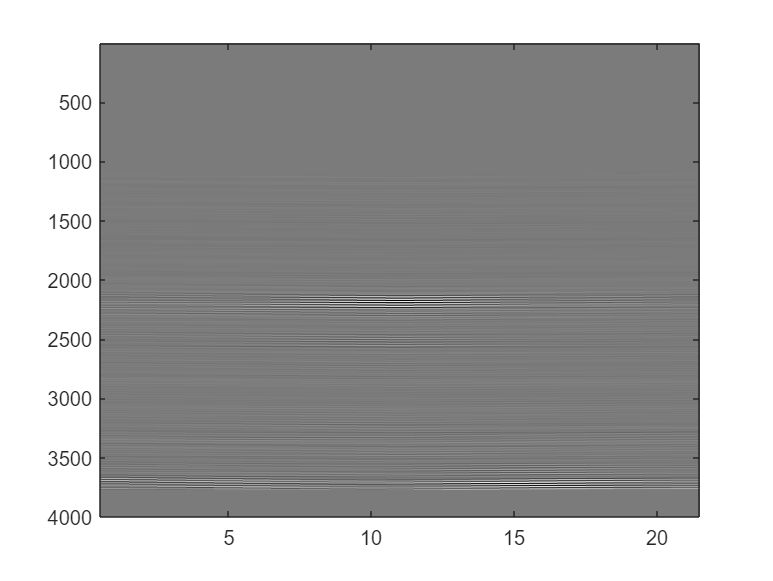


fig1 = figure;
figure(fig1);
colormap(gray);
imagesc(transpose(beams));

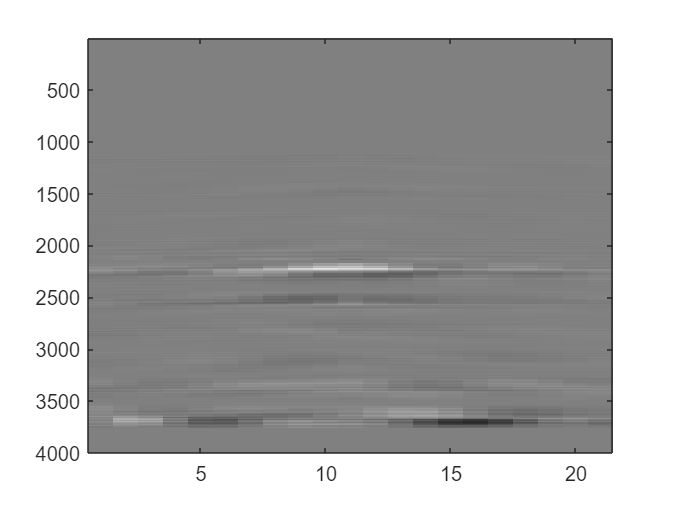


fig2 = figure;
figure(fig2);
colormap(gray);
imagesc(transpose(demod_I));

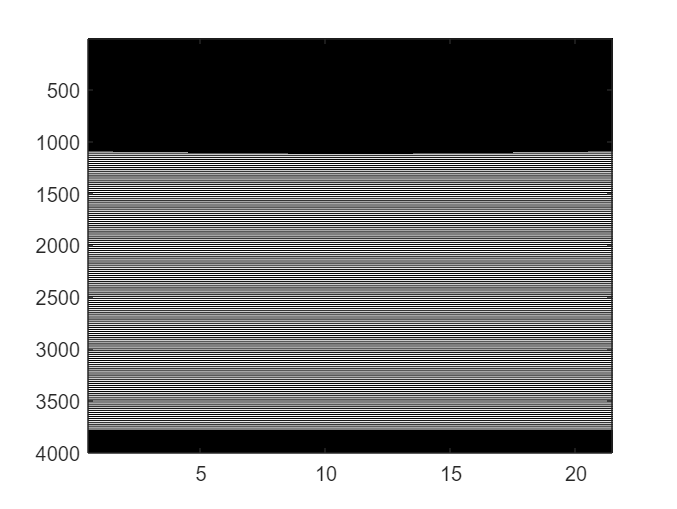


mixed = demod_I./beams;
fig3 = figure;
figure(fig3);
colormap(gray);
imagesc(transpose(mixed));

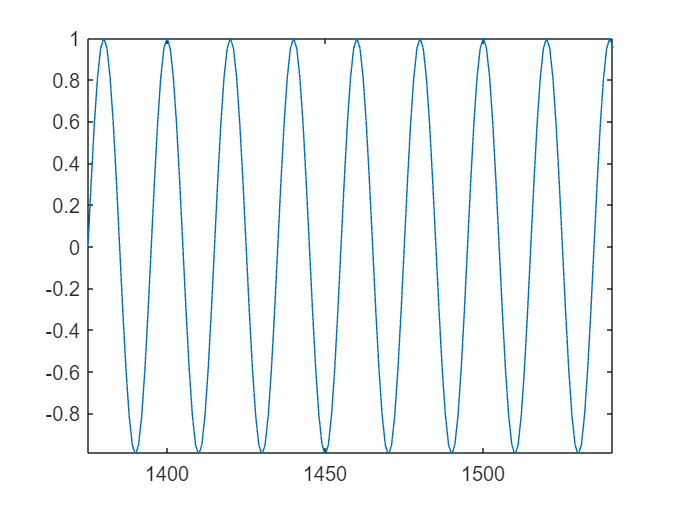


extract = mixed(10,:);
fig4 = figure;
figure(fig4);
plot(1:1:length(extract), extract)
xlim([1375 1541])
ylim([-0.99 1.00])